# Actividad_8.1 _SLAM_de_Lidar_parte2_exampleMap

% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.5;              % Sample time [s]
tVec = 0:sampleTime:175;        % Time array

% Initial conditions
initPose = [1;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical
%emptyMap         26x27                 702  logical
%simpleMap        26x27                 702  logical
%ternaryMap      501x501            2008008  double

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,360);%51
lidar.maxRange = 2;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
    2,10;
    11,8;
    8,2;
    8,6;
    6,8;
    3,4
    1,2];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.3;%0.5
controller.DesiredLinearVelocity = 0.3; %0.75
controller.MaxAngularVelocity = 0.3

controller =   controllerPurePursuit with properties:

                Waypoints: [8x2 double]
       MaxAngularVelocity: 0.3000
        LookaheadDistance: 0.3000
    DesiredLinearVelocity: 0.3000


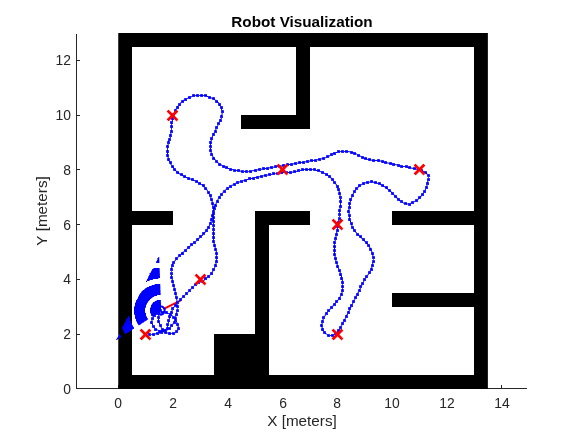


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 900; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.05;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec)

    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);

    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end

    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world

    % Check if goal is reached
    goal = waypoints(end,:);
    distToGoal = norm(pose(1:2,idx) - goal');
    if distToGoal < 0.2
        break;
    end

    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime;

    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end